# PI cascade controller for the DC motor

% Parameters
km = 2;
J = 20;
f = 0.1;
s = tf('s');
G = (km/f)/(J/f*s + 1) % Transfer function of inner closed-loop system

G =
 
     20
  ---------
  200 s + 1
 
Continuous-time transfer function.



## Outer PI-controller

tau_i = 2;
F = (tau_i*s + 1)/(tau_i*s)

F =
 
  2 s + 1
  -------
    2 s
 
Continuous-time transfer function.



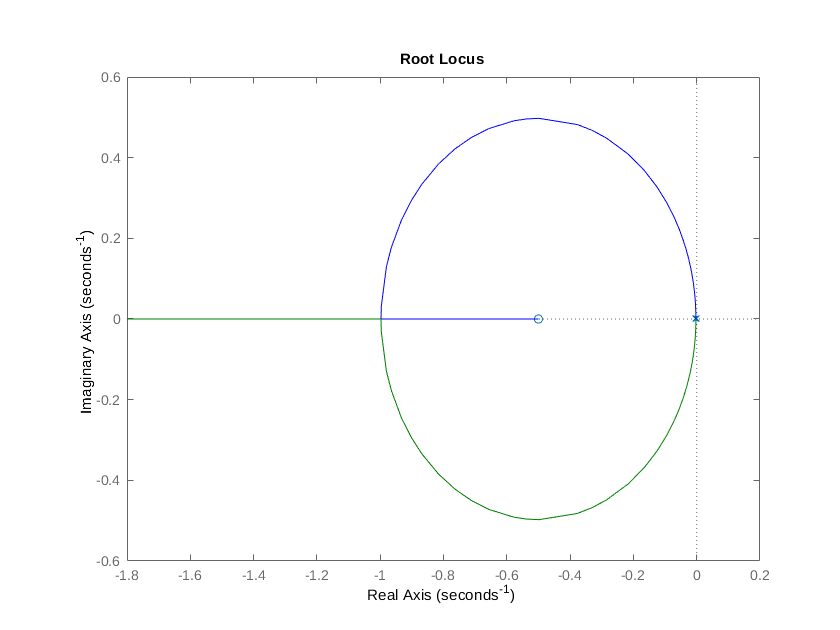

rlocus(G*F)


K = 19.9; % Gain


## Closed-loop system

Gc = feedback(K*F*G, 1)

Gc =
 
       796 s + 398
  ---------------------
  400 s^2 + 798 s + 398
 
Continuous-time transfer function.



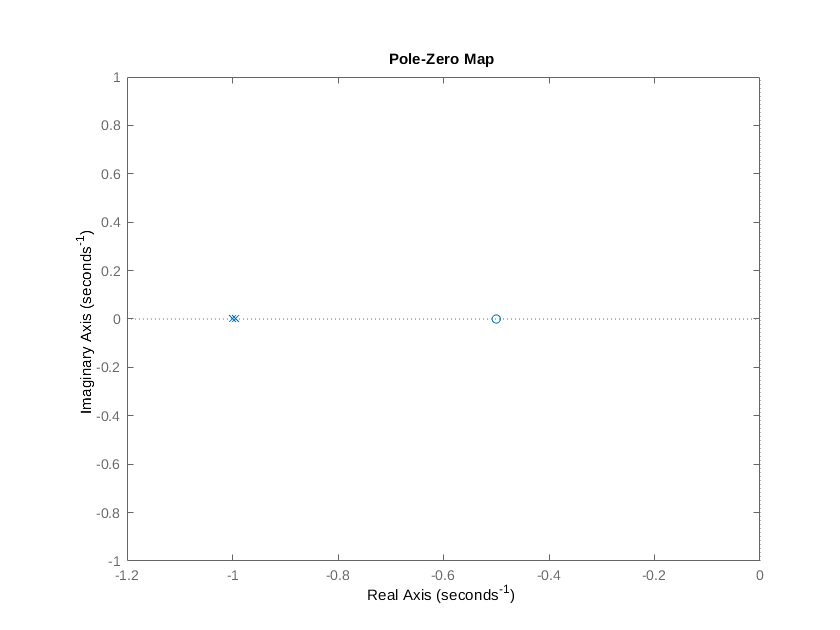

figure
pzmap(Gc)

pole(Gc)

ans =    -1.0000
   -0.9950
